# Process auditory_ephys_exp for analysis and visualization

## This script takes the experiment object, extracts and saves the relevant information for creating figures and running models

% Load experiment object
cd /media/ben/'Extreme SSD'/analysisData/ % optional 
[file,path] = uigetfile('*.mat');
cd(path)
load(file)

###  Create the time vectors for the experiment

update all the condition change times to not include artifacts and be in the range of the non discarded times

tempCondition = experiment.Conditions.all_changes

tempCondition(:,2) = [tempCondition(2:end,1);length(experiment.sound.full)]

% Clean the artifact after times from the conditions
timeAfter = experiment.Conditions.artifact_times(2)*30
tempCondition(:,1) = tempCondition(:,1) + timeAfter

% clean the artifact time before each change
timeBefore = experiment.Conditions.artifact_times(1)*30
tempCondition(:,2) = tempCondition(:,2)-timeBefore

if tempCondition(end,1) > tempCondition(end,2)
    tempCondition(end,:) = [];
end

% if ~isempty(experiment.time2discard)
%     experiment.time2discard = experiment.time2discard*30000
% end

if ~isempty(experiment.time2discard)
    if length(experiment.time2discard) > 1
        warning("Manually adjust condition times to discard bad recording times")
    else
        h = find(tempCondition >= experiment.time2discard)
        tempCondition(h) = [];
        tempCondition(end+1) = experiment.time2discard
        tempCondition = reshape(tempCondition,length(tempCondition)/2,2)
    end
end

experiment.Conditions.all_changesClean = tempCondition

experiment.Conditions.classificationCleaned = experiment.Conditions.condition_classification(1:length(tempCondition))

Align whisking times to ephys frames and create all whisking times mat

experiment.Whisking.long(experiment.Whisking.long > length(experiment.Cams.whisking.csv_aligned_frames)) = length(experiment.Cams.whisking.csv_aligned_frames)
experiment.Whisking.short(experiment.Whisking.short > length(experiment.Cams.whisking.csv_aligned_frames)) = length(experiment.Cams.whisking.csv_aligned_frames)
%experiment.Whisking.all(experiment.Whisking.all > length(experiment.Cams.whisking.csv_aligned_frames)) = length(experiment.Cams.whisking.csv_aligned_frames)

experiment.Whisking.long = experiment.Cams.whisking.csv_aligned_frames(experiment.Whisking.long)
experiment.Whisking.short = experiment.Cams.whisking.csv_aligned_frames(experiment.Whisking.short)
% experiment.Whisking.all = experiment.Cams.whisking.csv_aligned_frames(experiment.Whisking.all)

experiment.Whisking.all = [experiment.Whisking.long;experiment.Whisking.short]
experiment.Whisking.all = sort(experiment.Whisking.all)

% % if need redistribute whisking to long and short
% epochLength = experiment.Whisking.all(:,2) - experiment.Whisking.all(:,1);
% clear longEpoch
% start_epoch = experiment.Whisking.all(:,1);
% endEpoch = experiment.Whisking.all(:,2)
% longEpoch(:,1) = start_epoch(epochLength > 15000)
% longEpoch(:,2) = endEpoch(epochLength > 15000)
% clear shortEpoch
% shortEpoch(:,1) = start_epoch(epochLength <= 15000)
% shortEpoch(:,2) = endEpoch(epochLength <= 15000)
% experiment.Whisking.long = longEpoch
% experiment.Whisking.short = shortEpoch

create time vectors for each condition (no whisking, whisking: aluminum, attanuated, no object)

conV = experiment.getConVector

conV = struct with fields:
      aluminum: [1×14236033 int64]
         muted: [1×4241561 int64]
           non: [1×8479922 int64]
    noWhisking: [1×30504334 int64]
    fullVector: [1×57461850 int64]


experiment.conditionVector = conV

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [5105×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [1×67777279 double]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
                Whisking: [1×1 struct]
               timeStamp: []
            analysisType: {'sound events'  'continuous whisking'  'discrete whisking'  'no whisking periods'}
            time2discard: []


save experiment object

cd /media/ben/'Extreme SSD'/analysisData/
save([experiment.experiment_ID,'.mat'],'experiment','-v7.3')

experiment.experiment_ID

clearvars -except experiment
clc
close all


### Adjust unit times to the time vectors and conditions

Create a structure with each unit firiing rate in each condition

binSize = 0.4;

conditionsStats = experiment.getBinnedStats(binSize)

conditionsStats = struct with fields:
    unitsPerCon: [1×1 struct]
         binned: [1×1 struct]
            STD: [41×4 double]


FRVector = [conditionsStats.unitsPerCon.aluminum.FR,conditionsStats.unitsPerCon.muted.FR,conditionsStats.unitsPerCon.non.FR,conditionsStats.unitsPerCon.noWhisking.FR]

FRVector =     1.3719    2.7796    1.8998    2.3721
    2.3665    3.7628    2.5790    6.8144
    9.2765    1.2519    6.3927    0.5911
    4.2041    2.4896    3.5236    2.0515
   17.7922   19.3797   17.4094   13.6820
    1.8039    1.5277    1.5637    0.9127
    8.0142    7.1648    7.4788    4.2879
   16.1506    9.7252   14.8268    5.9126
   20.8204   16.8334   21.1948   18.5216
   17.2738   17.1941   18.6157   15.4424


experiment.Units.conditionsStats.FRVector = FRVector;
conditionsStats.FRVector = FRVector

conditionsStats = struct with fields:
    unitsPerCon: [1×1 struct]
         binned: [1×1 struct]
            STD: [41×4 double]
       FRVector: [41×4 double]


experiment.Units.conditionsStats = conditionsStats

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [5105×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [1×67777279 double]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
                Whisking: [1×1 struct]
               timeStamp: []
            analysisType: {'sound events'  'continuous whisking'  'discrete whisking'  'no whisking periods'}
            time2discard: []


corrcoef([FRVector])

ans =     1.0000    0.9620    0.9773    0.8998
    0.9620    1.0000    0.9831    0.9058
    0.9773    0.9831    1.0000    0.8918
    0.8998    0.9058    0.8918    1.0000


add to object and save

cd /media/ben/'Extreme SSD'/analysisData/
save([experiment.experiment_ID,'.mat'],'experiment','-v7.3')

cd /media/ben/'Extreme SSD'/analysisData/conditionV/
save([experiment.experiment_ID,'ConVec.mat'],'conditionsStats','-mat')

experiment.experiment_ID

ans = 'FVB109_1023'

clearvars -except experiment
clc
close all


### Get All PSTH for sound driven events and save them for collective analysis

FR and rasters locked to the sound in aluminum condition

% Load experiment object
cd /media/ben/'Extreme SSD'/analysisData/ % optional 
[file,path] = uigetfile('*.mat');
cd(path)
load(file)

notTooShort = experiment.sound_events(:,2) - experiment.sound_events(:,1)

notTooShort =          694
          25
          26
        1865
        1343
        1186
         195
           0
         576
        1196



notTooShortInd = notTooShort > 60

notTooShortInd = 3635×1 logical array
   1
   0
   0
   1
   1
   1
   1
   0
   1
   1


longEvents = experiment.sound_events(notTooShortInd,1)

longEvents =         3816
       44488
      151278
      166321
      182412
      211539
      226396
      241478
      271490
      273585


%longEvents([false;diff(longEvents) < 750]) = []

aluminumSoundEvents = intersect(experiment.conditionVector.aluminum,longEvents)

aluminumSoundEvents = 1232×1 int64 column vector
   19843507
   19848419
   19850503
   19851262
   19852105
   19853749
   19856394
   19860455
   19863271
   19867570


mutedSoundEvents = intersect(experiment.conditionVector.muted,longEvents)

mutedSoundEvents = 24×1 int64 column vector
   27458587
   27547668
   28053933
   28064658
   28149682
   29009782
   39957844
   40710413
   40770261
   40969652


nonSoundEvents = intersect(experiment.conditionVector.non,longEvents)

nonSoundEvents = 53×1 int64 column vector
    6823994
    6839802
    7155363
    8102510
   18506391
   18511160
   18521328
   18527970
   18529498
   18534300


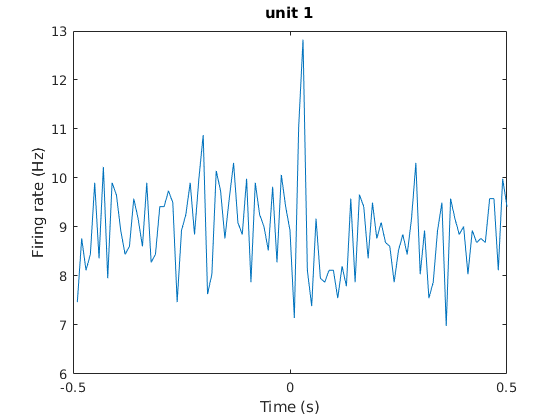

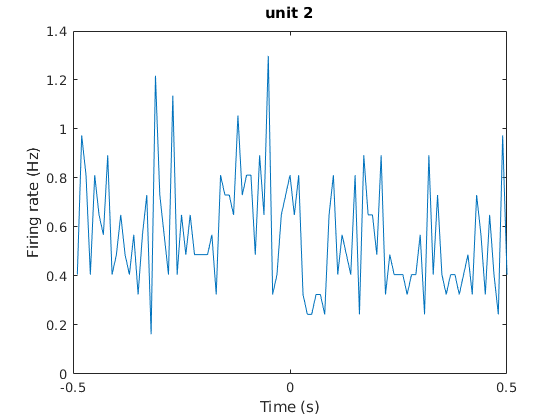

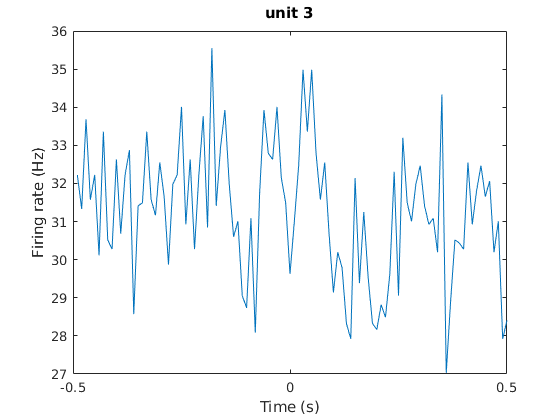

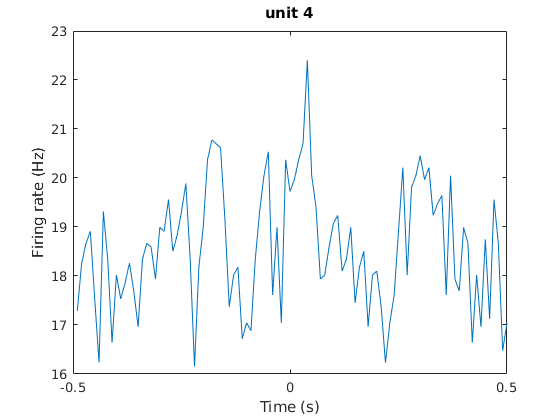

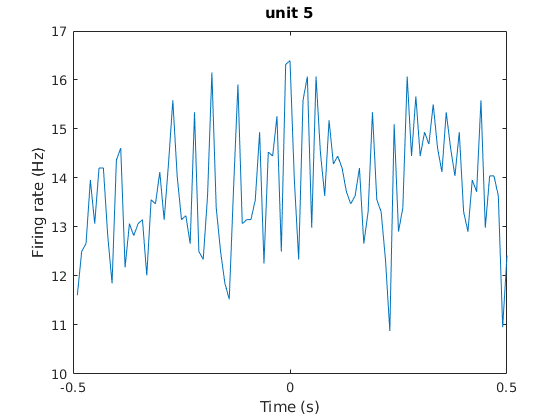

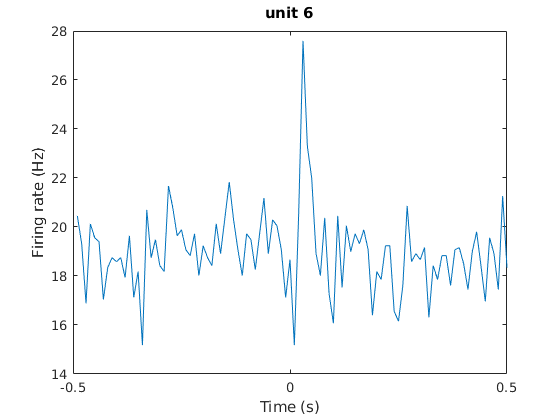

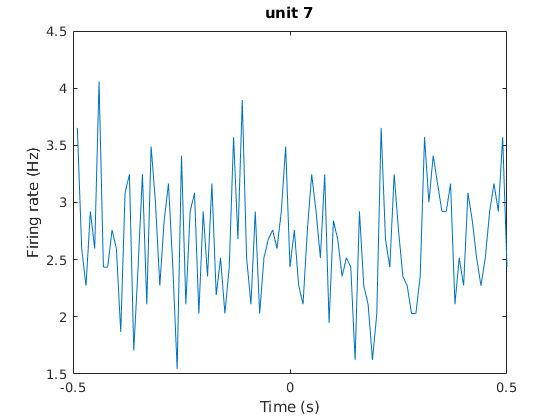

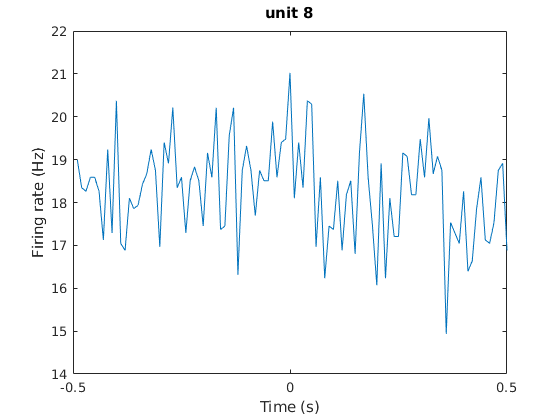

[all_psth] = mean_psth(double(aluminumSoundEvents),experiment.Units,1,10);

normalizedP = normalize(all_psth.United,2)

normalizedP =    -1.5769   -0.1806   -0.8788   -0.5297    1.0411   -0.6170    1.3901   -1.0533    1.0411    0.7793   -0.0061   -0.5297   -0.3552    0.6920    0.2557   -0.3552    1.0411   -0.7042   -0.5297    0.5175    0.5175    0.8665    0.6047   -1.5769   -0.0061    0.3429    1.0411   -0.0934    1.1283    2.0882   -1.4023   -0.9660    1.3029    0.8665   -0.1806    0.6920    1.4774    0.1684   -0.0934    1.1283   -1.1405    1.0411    0.3429    0.0812   -0.4424    0.9538   -0.7042    1.2156    0.5175   -0.0061
   -0.6853    1.7622    1.0629   -0.6853    1.0629    0.3636    0.0140    1.4125   -0.6853   -0.3357    0.3636   -0.3357   -0.6853    0.0140   -1.0349    0.0140    0.7133   -1.7342    2.8111    0.7133    0.0140   -0.6853    2.4614   -0.6853    0.3636   -0.3357    0.3636   -0.3357   -0.3357   -0.3357   -0.3357    0.0140   -1.0349    1.0629    0.7133    0.7133    0.3636    2.1118    0.7133    1.0629    1.0629   -0.3357    1.4125    0.3636    3.1607   -1.0349   -0.6853    0.3636    0

FRRank = max(normalizedP(:,49:55)')

FRRank =     4.1826    1.0629    2.0936    3.0807    2.1019    5.1822    1.5625    2.4091    1.9512    2.9174    2.1041    1.4477    0.4299    2.1143    3.0322    2.0937    1.2267    1.7482    1.8916    3.0490    2.9433    2.2939    2.9406    3.6887    1.7964    1.0527    2.0816   -0.4236    2.5776    2.8654    4.7574


[sorteP,ind] = sort(FRRank,"descend")

sorteP =     5.1822    4.7574    4.1826    3.6887    3.0807    3.0490    3.0322    2.9433    2.9406    2.9174    2.8654    2.5776    2.4091    2.2939    2.1143    2.1041    2.1019    2.0937    2.0936    2.0816    1.9512    1.8916    1.7964    1.7482    1.5625    1.4477    1.2267    1.0629    1.0527    0.4299   -0.4236


ind =      6    31     1    24     4    20    15    21    23    10    30    29     8    22    14    11     5    16     3    27     9    19    25    18     7    12    17     2    26    13    28


normalizedP = normalizedP(ind,:)

normalizedP =     0.8792    0.1946   -1.2723    0.6836    0.3413    0.2435   -1.1745   -0.3922   -0.1477   -0.2455   -0.1477   -0.6366    0.3902   -1.1256   -0.4900   -2.2992    1.0259   -0.1477    0.2924   -0.3433   -0.4900    1.6126    1.0748    0.3902    0.5369    0.0479   -0.0988    0.4391   -0.5877    0.1457   -0.1477   -0.3433    0.6836   -0.0499    0.8303    1.7104    0.7814    0.0479   -0.5877    0.4391    0.2924   -0.4411    0.4391    1.3193   -0.0499    0.7814    0.6347    0.0479   -1.1256   -0.1966
   -0.0811    1.1997    1.4843   -0.9350   -0.5080   -0.7927    0.4881    0.4881    0.2035   -0.5080    0.2035   -0.9350    0.2035   -0.5080   -0.3657   -0.5080    0.6304    0.0612   -0.2234    0.9150    0.7727   -0.6503    0.3458   -0.9350    1.0573   -0.0811   -0.7927    0.4881   -0.3657    1.0573    0.9150    0.4881    0.6304   -0.0811    0.7727   -0.0811   -0.2234    0.3458    0.2035   -0.2234   -0.5080    0.9150    1.6266   -0.3657   -0.3657    0.4881   -0.3657    0.4881   -0

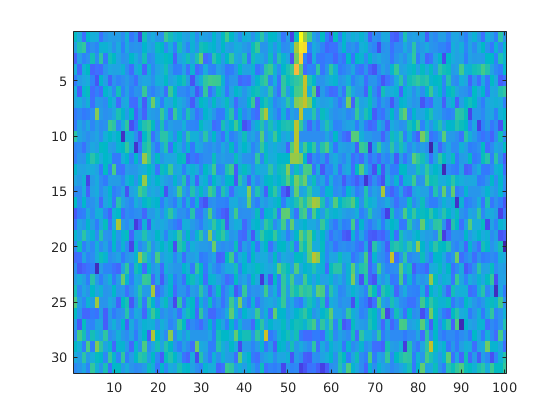

imagesc(normalizedP)

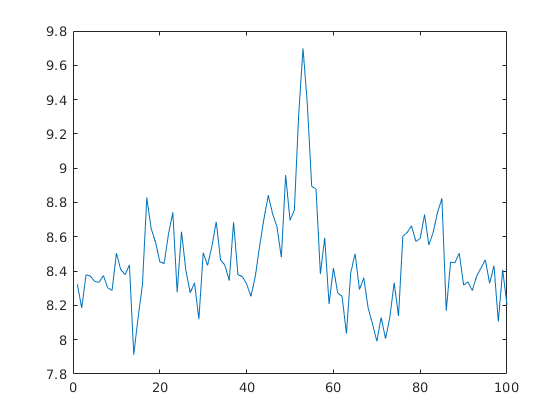

figure;
plot(mean(all_psth.United))

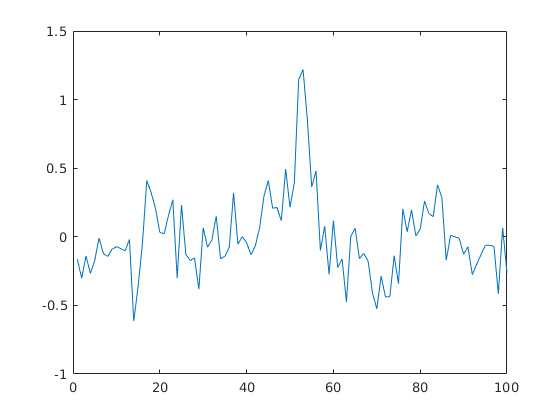

figure;
plot(mean(normalizedP))

all_psth.alumSoundEvents = aluminumSoundEvents;

soundMat =meanMatrix(double(all_psth.alumSoundEvents),1,30000);
soundMat = experiment.sound.smoothed(soundMat);

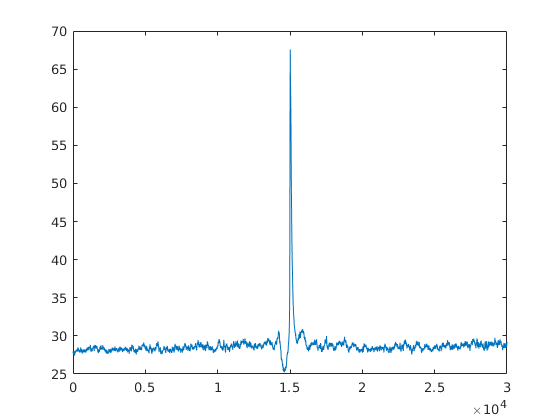

figure; plot(mean(soundMat))

all_psth.soundMat = soundMat;

cd /media/ben/'Extreme SSD'/analysisData/aluminumAudio/
save([experiment.experiment_ID,'audUnits.mat'],'all_psth','-mat')

clear 
clc
close all